## **choose** the data along a line along any direction and then fit the data going outside.

`This file has the use of table and the set of plot parameter which is very useful.`

THis file should follow "boundary_study.m". It will take the parameter from the other file.

This is for big magnetic field

%initial the arrays need to keep 
phi_fit = 1/2*pi; % choose a direction on the pattern for fitting.
number_fit_data = 1000;
xmn_test = zeros(1,number_fit_data);
ymn_test = zeros(1,number_fit_data);
initial_theta = linspace(1/1000*pi/2, 1000/1000*pi/2,number_fit_data);
flag    = zeros(1,number_fit_data);
flag2   = zeros(1,number_fit_data);
amp_test_1 = zeros(1,number_fit_data);
amp_test_2 = zeros(1,number_fit_data);
s_test_1   = zeros(1,number_fit_data);
s_test_2   = zeros(1,number_fit_data);
sum_s_test = zeros(1,number_fit_data);
zeta_test  = zeros(1,number_fit_data);
amp_test_m = zeros(1,number_fit_data);
amp_test_p = zeros(1,number_fit_data);
gamma_test = zeros(1,number_fit_data);
delta_test = zeros(1,number_fit_data);
amp_airya_test = zeros(1,number_fit_data);
radius = zeros(1,number_fit_data);
% x_choose_fit = linspace(x_begin_fit,x_end_fit,number_fit_data);
options = optimoptions('fsolve','Display','none');
options.Algorithm = 'levenberg-marquardt';
options.StepTolerance = 1.00e-8;
for i = linspace(1,number_fit_data,number_fit_data)
    phi_fit_sys = ppval(pattern_sys,phi_fit);
% small magnetic field
%     phi_fit_sys = phi_fit;
    tx_test = real(tmax_num(phi_fit_sys,initial_theta(i)));
    radius(i) = ((xSol_num(tx_test,phi_fit_sys,initial_theta(i)) - xmn(1))^2 ...
        +(ySol_num(tx_test,phi_fit_sys,initial_theta(i)))^2)^(1/2) ;
    xmn_test(i) = xmn(1) + radius(i) *cos(phi_fit);
    ymn_test(i) = radius(i)*sin(phi_fit);
    fun2 = @(ang)[real(xDetect(ang(1), ang(2))-xmn_test(i)) ;
    real(yDetect(ang(1), ang(2))-ymn_test(i))];
    x0 = [phi_fit_sys , initial_theta(i)];
    x1 = [ phi_fit_sys, pi - initial_theta(i)];
    [mm1,MML,flag(i),MMM] = fsolve(fun2,x0, options);
    [mm2,MML2,flag2(i),MMM2] = fsolve(fun2,x1,options);
    tx_test_1 = real(tmax_num(mm1(1),mm1(2)));
    tx_test_2 = real(tmax_num(mm2(1),mm2(2)));
%     variables below can be saved for debuging, Later can just be taken as  intermediate variables
    amp_test_1(i) = abs(Jacob(0,mm1(1),mm1(2))/Jacob(tx_test_1,mm1(1),mm1(2)))^(1/2);
    amp_test_2(i) = abs(Jacob(0,mm2(1),mm2(2))/Jacob(tx_test_2,mm2(1),mm2(2)))^(1/2);
    s_test_1(i)   = action(mm1(1),mm1(2));
    s_test_2(i)   = action(mm2(1), mm2(2));
    sum_s_test(i)  = s_test_1(i) +s_test_2(i);
    zeta_test(i) = (3/4*(s_test_1(i) - s_test_2(i)))^(2/3);
%     vaiables below is useful
% % for s-wave firstly
%     amp_test_m(i) = amp_test_2(i) - amp_test_1(i);
%     amp_test_p(i) = amp_test_2(i) + amp_test_1(i);
% %     for p0-wave
%     amp_test_m(i) = amp_test_2(i)*cos(mm2(2))-amp_test_1(i)*cos(mm1(2));
%     amp_test_p(i) = amp_test_2(i)*cos(mm2(2))+amp_test_1(i)*cos(mm1(2));
%    for p1-wave
    amp_test_m(i) = amp_test_2(i)*sin(mm2(2))*exp(1i*mm2(1))-amp_test_1(i)*sin(mm1(2))*exp(1i*mm1(1));
    amp_test_p(i) = amp_test_2(i)*sin(mm2(2))*exp(1i*mm2(1))+amp_test_1(i)*sin(mm1(2))*exp(1i*mm1(1));
%  amp_test_m(i + j*num_theta_fit) = amp_test_2*sin(mm2(2))*exp(1i*mm2(1))-amp_test_1*sin(mm1(2))*exp(1i*mm1(1));
%         amp_test_p(i + j*num_theta_fit) = amp_test_2*sin(mm2(2))*exp(1i*mm2(1))+amp_test_1*sin(mm1(2))*exp(1i*mm1(1));
    
    gamma_test(i) = sqrt(pi)*exp(1i*sum_s_test(i))*amp_test_p(i)*zeta_test(i)^(1/4);
    delta_test(i) = sqrt(pi)*exp(1i*sum_s_test(i))*amp_test_m(i)*zeta_test(i)^(-1/4);
    amp_airya_test(i) = abs(gamma_test(i)*airy(-zeta_test(i))-1i*delta_test(i)*airy(1,-zeta_test(i)))^2;
end

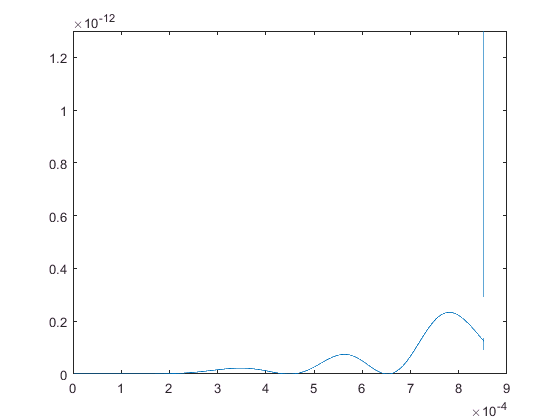

plot(radius*L_au,amp_airya_test)
ylim([0 1.3*10^-12])

num_beg = 700;
num_end = 970;

fit_test_p = amp_test_p(num_beg:num_end).*zeta_test(num_beg:num_end).^(1/4);  % 
fit_test_p_real = real(fit_test_p);
fit_test_p_imag = imag(fit_test_p);
fit_test_m = amp_test_m(num_beg:num_end).*zeta_test(num_beg:num_end).^(-1/4);
fit_test_m_real = real(fit_test_m);
fit_test_m_imag = imag(fit_test_m);
radius_test = radius(num_beg:num_end)*L_au;
[f_test_p_real ,gof_test_p] = fit(radius_test',fit_test_p_real','poly2');
[f_test_p_imag ,gof_test_p] = fit(radius_test',fit_test_p_imag','poly2');
% figure();
% plot(f_test_p,radius_test,fit_test_p)
% hold on;
% plot(radius_exp,f_test_p(radius_exp))
% hold off;
[f_test_m_real ,gof_test_m] = fit(radius_test',fit_test_m_real','poly2');
[f_test_m_imag ,gof_test_m] = fit(radius_test',fit_test_m_imag','poly2');

f_test_p = @(x) f_test_p_real(x)+1i*f_test_p_imag(x);
f_test_m = @(x) f_test_m_real(x) + 1i*f_test_m_imag(x);




% figure();
% hold on;
% plot(f_test_m,radius_test,fit_test_m)
% plot(radius_exp,f_test_m(radius_exp));
% hold off;
[fs_test_p , gof_test_sp] = fit(radius_test',sum_s_test(num_beg:num_end)','poly1');
[fs_test_m , gof_test_sm] = fit(radius_test',zeta_test(num_beg:num_end)','poly1');
% plot(fs_test_m,radius_test,zeta_test(num_beg:num_end));




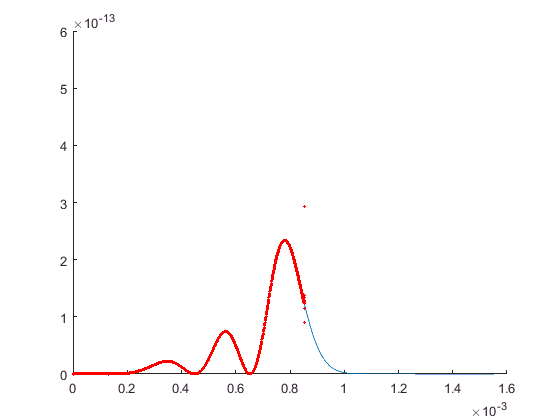

radius_exp = linspace(radius_test(1),radius_test(end)+0.7*10^-3,400);
amp_test_fit = abs(sqrt(pi)*exp(1i*fs_test_p(radius_exp)).*f_test_p(radius_exp) ...
    .*airy(-fs_test_m(radius_exp))-1i*sqrt(pi)*exp(1i*fs_test_p(radius_exp)).*f_test_m(radius_exp) ...
    .*airy(1,-fs_test_m(radius_exp))).^2;
figure();

hold on;
plot(radius_exp,amp_test_fit)
% plot(radius_test,amp_airya_test(num_beg:num_end),'*r','MarkerSize',1)
plot(radius*L_au,amp_airya_test,'*r','MarkerSize',1)
ylim([0 6*10^-13])
hold off;

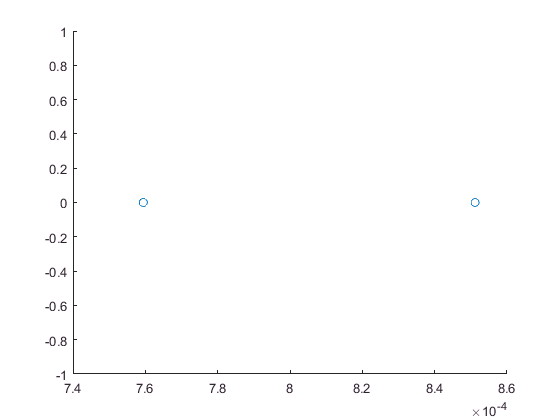

radius_final_1d = [radius(1:num_beg-1)*L_au radius_exp]*10^3;
amp_final_1d    = [amp_airya_test(1:num_beg-1) amp_test_fit'];
% size_amp = size(radius_final_1d);
% amp_final_sum =size_amp(1)^(-1)*sum(amp_final_1d);
amp_final_1d = amp_final_1d/normalization_amp*10^-6;

scatter([radius(num_beg)*L_au radius(num_end)*L_au],[0 0])

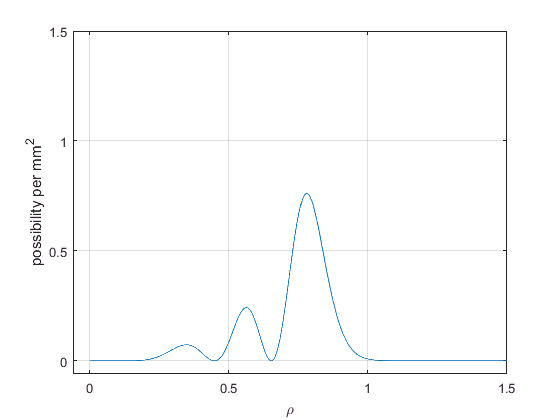

figure();
box on;
hold on
plot(radius_final_1d , amp_final_1d)
% plot(radius_final_1d_y,amp_final_1d_y)
%axis([-0.1*10^-3 inf -6*10^4 15*10^5])
axis([-0.06 1.5 -0.06 1.5])
% legend('x-direction','y-direction','Location','best')
xlabel('\rho')
ylabel('possibility per mm^2')
axis fill
grid on
hold off

% every time after running this program , get the data and add to the table.
Table_add = {"B60P1Phi90",radius_final_1d,amp_final_1d,normalization_amp}

Table_add = 1×3 cell array
    ["B60P1Phi90"]    [1×1099 double]    [1×1099 double]

TableOneDimen = [TableOneDimen ; Table_add]

Table_new = 3×3 table
     Situation          Radius         PossibilityDensity
    ____________    _______________    __________________
    "B60P1Phi0"     [1x1099 double]    [1x1099 double]   
    "B60P1Phi45"    [1x1099 double]    [1x1099 double]   
    "B60P1Phi90"    [1x1099 double]    [1x1099 double]   

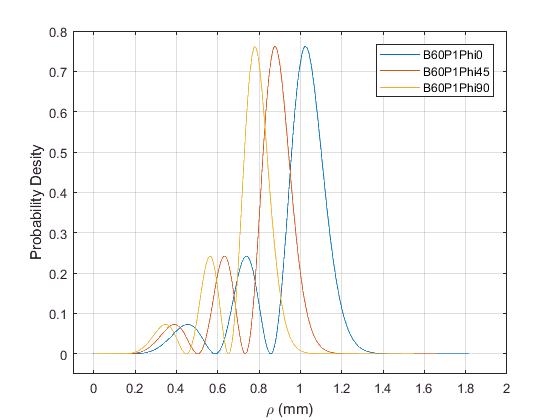

figure();
hold on;
plot(TableOneDimen{1,2},TableOneDimen{1,3});
plot(TableOneDimen{2,2},TableOneDimen{2,3});
plot(TableOneDimen{3,2},TableOneDimen{3,3});
legend(TableOneDimen{:,1});
xlabel('\rho (mm)')
ylabel('Probability Desity');
grid on;
box on;
axis([-0.1 2 -0.05 0.8]);
hold off;

% NormalPara = [normalization_amp ; normalization_amp ; normalization_amp];
% Table_col = table(NormalPara);
% Table_new2 = [Table_new Table_col]
% TableOneDimen = Table_new2

TableOneDimen = 3×4 table
     Situation          Radius         PossibilityDensity    NormalPara
    ____________    _______________    __________________    __________
    "B60P1Phi0"     [1x1099 double]    [1x1099 double]       3.0704e-19
    "B60P1Phi45"    [1x1099 double]    [1x1099 double]       3.0704e-19
    "B60P1Phi90"    [1x1099 double]    [1x1099 double]       3.0704e-19


% Situation = {'B60P1Phi0'; 'B60P1Phi45'};
% Radius    = [radius_final_1d_y;radius_final_1d];
% PossibilityDensity =[amp_final_1d_y;amp_final_1d];
% 

% TableOneDimen = table(Situation,Radius,PossibilityDensity)